warning('off','all')
% Convert timetables output from DFD to array
% Combine time domain features with frequency domain features
% Output is an array numOfPulses x numOfSignals x numOfFeatures
numOfTimeFeatures = size(featureNames, 2);
numOfFreqFeatures = size(featureNames_Freq, 2);
numOfPulses = size(pulseData_Timetable, 1);
totalFeatures = numOfTimeFeatures + numOfFreqFeatures;
featureArray = zeros(numOfPulses, totalFeatures, numOfSignals);
for signalIndex = 1 : numOfSignals
    for featureIndex = 1 : numOfTimeFeatures
        featureArray(:, featureIndex, signalIndex) = FeaturesAll.(signalName(signalIndex) + featureNames(featureIndex));
    end
    for featureIndex = 1 : numOfFreqFeatures
        featureArray(:, featureIndex + numOfTimeFeatures, signalIndex) = FeaturesAll.(signalName(signalIndex) + featureNames(featureIndex));
    end   
end
signalIndex = 5;
combinedFeatureNames = [featureNames featureNames_Freq]

combinedFeatureNames = 1×16 string array
    "ClearanceFactor"    "CrestFactor"    "ImpulseFactor"    "Kurtosis"    "Mean"    "PeakValue"    "RMS"    "SNR"    "SINAD"    "ShapeFactor"    "Skewness"    "Std"    "THD"    "BandPower"    "PeakAmp1"    "PeakFreq1"


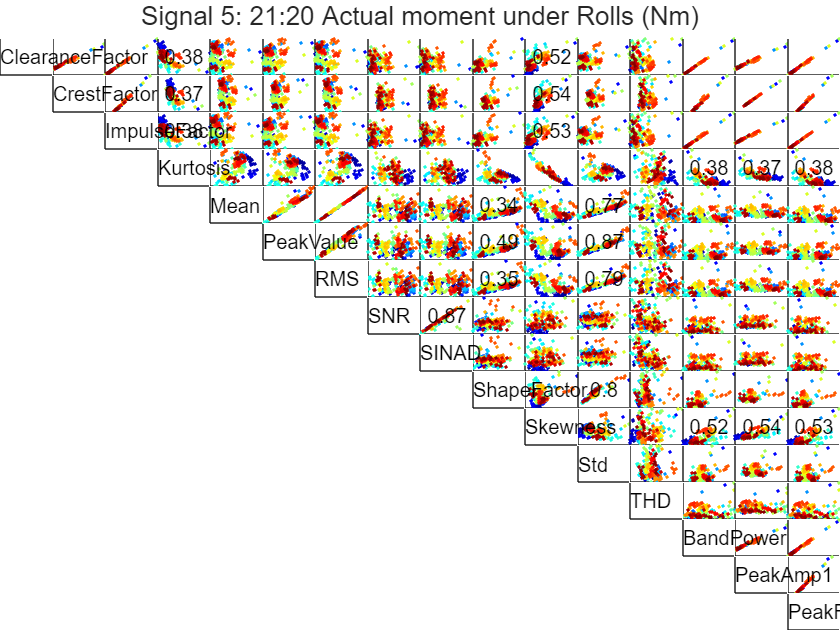

R2 = fnPlotFeatureVsFeature_Array(featureArray, signalIndex, 0.3, 0.9, combinedFeatureNames, sensorNames);

function [R2] = fnPlotFeatureVsFeature_Array(featureArray, signalIndex, lowerBound, upperBound, featureNames, sensorNames)
    figure();
    numpoints = size(featureArray, 1); 
    numOfFeatures = size(featureArray, 2);
    t = tiledlayout(numOfFeatures, numOfFeatures, 'TileSpacing','None', 'Padding','tight');
    title(t, "Signal " + signalIndex + ": " + sensorNames(signalIndex));
    R2 = zeros(numOfFeatures, numOfFeatures);
    pointidx = 1 : numpoints;
    % Loop through features
    for featureIndex1 = 1:numOfFeatures
        % Loop through features
        for featureIndex2 = featureIndex1+1:numOfFeatures
            sig1 = featureArray(:, featureIndex1, signalIndex);
            sig2 = featureArray(:, featureIndex2, signalIndex);

            mdl = fitlm(sig1, sig2);
            R2(featureIndex1, featureIndex2) = mdl.Rsquared.Ordinary;

            nexttile((featureIndex1-1) * numOfFeatures + featureIndex2);            
            scatter(sig1, sig2, 3, pointidx, 'filled');
            colormap( jet(numpoints) );
            xticklabels({});
            yticklabels({});

            DataX = interp1( [0 1], xlim(), 0.5 );
            DataY = interp1( [0 1], ylim(), 0.5 );

            if R2(featureIndex1, featureIndex2) > lowerBound && R2(featureIndex1, featureIndex2) < upperBound
                text(DataX, DataY, num2str(R2(featureIndex1, featureIndex2), 2), 'HorizontalAlignment','center');
            end
        end
    end
    for featureIndex = 1 : numOfFeatures
        nexttile((featureIndex-1) * numOfFeatures + featureIndex);
        text(0, 0.5, featureNames(featureIndex));
        xticklabels({});
        yticklabels({});
    end
end